clc, clear
load('Lab4_Ass2.mat');
R = 33;
C = 1e-4;
Time = 2;
Fs = 400;
N = Time*Fs;

% a = strings(N,1);
% 
% s = serialport("COM8",57600);
% configureTerminator(s,"CR/LF");
% for i = 1:N
%     a(i,:) = readline(s);
% end
% b = double(a);
% clear s
b = Lab4_Ass2;

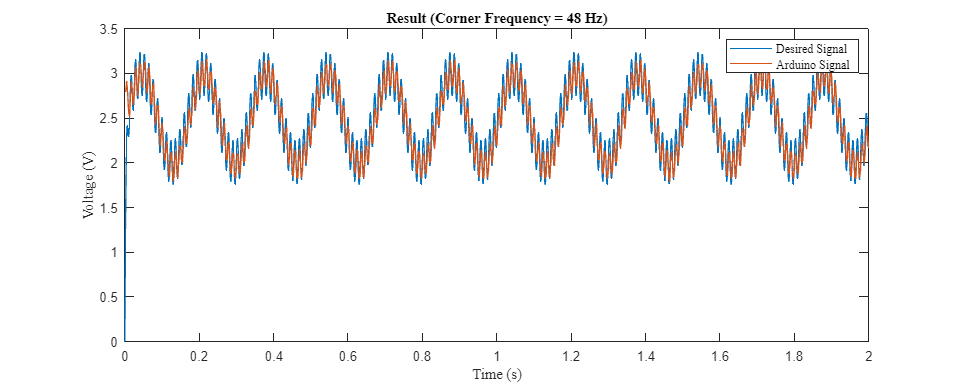

close all
syms t s
tt = 0 : 0.001 : 2;
generated = 0.5*sin(2*pi*6*t)+0.5*sin(2*pi*84*t)+2.5;
G1 = laplace(generated);
G = 1/(R*C*s+1);
clear f
f(t) = simplify(ilaplace(G1*G,t));

fig1 = figure("Name","b");
plot(tt,f(tt));
hold on
b1 = b/1023*5;
tt = 1/Fs : 1/Fs : Time;
plot(tt, b1)
title("Result (Corner Frequency = 48 Hz)", "FontName", "Times New Roman");
xlabel("Time (s)", "FontName", "Times New Roman");
ylabel("Voltage (V)", "FontName", "Times New Roman");
set(fig1, 'Units', 'Inches');
legend("Desired Signal", "Arduino Signal", "FontName", ...
    "Times New Roman")
set(fig1, 'Position', [0, 0, 10, 4]);
set(fig1, 'PaperPositionMode', 'auto');
exportgraphics(fig1, 'Assignment2_Response.png', 'Resolution', 600);
hold off

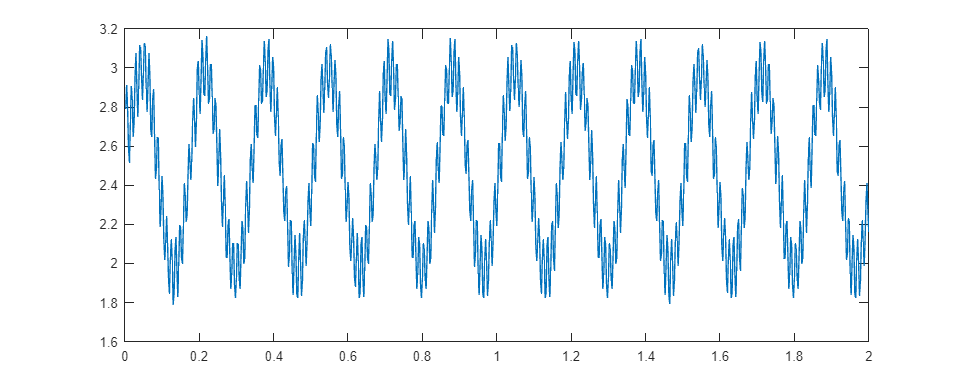

hnning_var = hann(N);

hanned = (b1-2.5).*hnning_var;

plot(tt, b1)

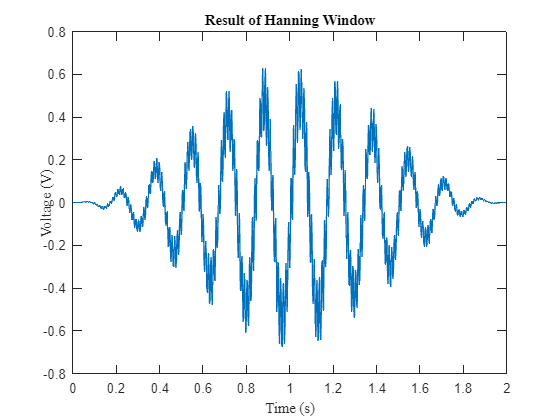

fig3 = figure("Name","d");
plot(tt, hanned)
title("Result of Hanning Window", "FontName", "Times New Roman");
xlabel("Time (s)", "FontName", "Times New Roman");
ylabel("Voltage (V)", "FontName", "Times New Roman");
set(fig3, 'Units', 'Inches');
set(fig3, 'Position', [0, 0, 10, 4]);
set(fig3, 'PaperPositionMode', 'auto');
exportgraphics(fig3, 'hanned.png', 'Resolution', 600);

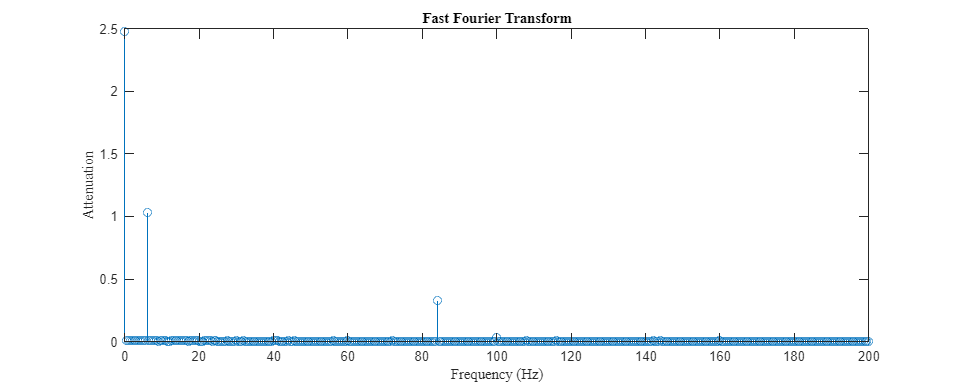



Y=fft(b1);

Y(1) = Y(1)/2;
P2 = abs(Y/(N/2));
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;
fig2 = figure("Name","a");
stem(f,P1)
title("Fast Fourier Transform", "FontName", "Times New Roman");
xlabel("Frequency (Hz)", "FontName", "Times New Roman");
ylabel("Attenuation", "FontName", "Times New Roman");
set(fig2, 'Units', 'Inches');
set(fig2, 'Position', [0, 0, 10, 4]);
set(fig2, 'PaperPositionMode', 'auto');
exportgraphics(fig2, 'FFT_Assignemt2.png', 'Resolution', 600);

[pks, locs] = findpeaks(P1, 'MinPeakHeight', 0.01); % You may need to adjust threshold
peak_freqs = f(locs);
peak_amps = pks;

% Display peaks
disp(table(peak_freqs', peak_amps, 'VariableNames', {'Frequency_Hz', 'Amplitude'}));

    Frequency_Hz    Amplitude
    ____________    _________

          6           1.0343 
         84          0.33228 
        100         0.029199 



fc = 1/(2*pi*R*C);  % Example cutoff frequency in Hz

H_theoretical = @(f) 1 ./ sqrt(1 + (f./fc).^2);

% Calculate theoretical gains at 6 Hz and 84 Hz
atten_6 = H_theoretical(6);
atten_84 = H_theoretical(84);

fprintf("Theoretical attenuation at 6 Hz: %.4f\n", atten_6);

Theoretical attenuation at 6 Hz: 0.9924


fprintf("Theoretical attenuation at 84 Hz: %.4f\n", atten_84);

Theoretical attenuation at 84 Hz: 0.4979
